#### Ans. 1

#### About : The data consists of 1-second measurements from pressure sensor collected in 5400 sec bursts every 3 hours. There are 200 bursts. 

load CMI_data.mat;
[N,Nburst] = size(CMI.p7);

#### The function SigWaveHt performs Fourier transformation on input data of a location point. 

#### Using parseval's theorem, we get the Sea swell Height and Infra gravity Height as output

[Hss7,Hig7] = SigWaveHt(CMI.e7,1,2);
[Hss6,Hig6] = SigWaveHt(CMI.p6,1,2);
[Hss3,Hig3] = SigWaveHt(CMI.p3,1,2);
[Hss2,Hig2] = SigWaveHt(CMI.p2,1,2);
t = mean(CMI.t);
t = datetime(datevec(t));

#### Ans. 2(a)

#### Plotting the Sea Swell Height for location 2, 3, 6 and 7

plot(t,Hss7,t,Hss6,t,Hss3,t,Hss2);
ylabel('HSS in meters')
xlabel('Time')
legend('7','6','3','2')
title('Sea Swell Significant Wave height')

### The sensor 7 has the highest Sea Swell Height

#### Ans. 2(b)

#### Plotting the Infragravity Height for location 2, 3, 6 and 7

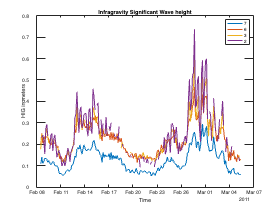

plot(t,Hig7,t,Hig6,t,Hig3,t,Hig2);
ylabel('HIG in meters')
xlabel('Time')
legend('7','6','3','2')
title('Infragravity Significant Wave height')

### The sensor 2 has the highest Infragravity Wave Height

### Ans 3

### Plotting the tidal variation considering burst-averaged water depth as a proxy

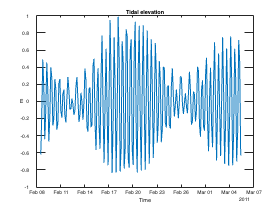

figure(3)
plot(t,detrend(mean(CMI.p7)))
ylabel('m')
xlabel('Time')
title('Tidal elevation')

#### The HSS at location 2 ,3 and 6 resemble the tidal height variation.

#### For example, The neap tide is distinctively visible on dates ~ 13 and 26 february in plots of HSS2, HSS3, HSS6 and tidal variation.

**The incident wave height corresponds to location 7 with HSS much higher than others. The tidal variation for location 7 is NOT similar to its HSS/HIG**

#### Ans 4. The function auto_spc computes autospectrum (S) as a function of frequency (f) for input time

[hmax,hindex] = max(Hss7)

hmax = 2.0413

hindex = 166

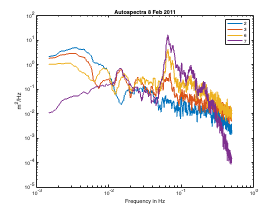

%Maximum height occurs on Feb 8 which is at index 166
[S2,Su2,Sl2,f2] = auto_spc(detrend(CMI.p2(:,166),2),1,15,0.05,1);
[S3,Su3,Sl3,f3] = auto_spc(detrend(CMI.p3(:,166),2),1,15,0.05,1);
[S6,Su6,Sl6,f6] = auto_spc(detrend(CMI.p6(:,166),2),1,15,0.05,1);
[S7,Su7,Sl7,f7] = auto_spc(detrend(CMI.p7(:,166),2),1,15,0.05,1);
loglog(f2,S2,f3,S3,f6,S6,f7,S7)
title('Autospectra 8 Feb 2011')
xlabel('Frequency in Hz')
ylabel('m^2/Hz')
legend('2','3','6','7')

[hmax,hindex] = max(Hss7)

hmax = 2.0413

hindex = 166

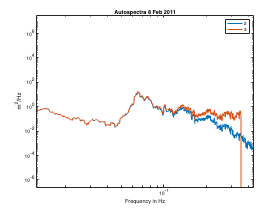

%Maximum height occurs on Feb 8 which is at index 166
[Se7,Sue7,Sle7,fe7] = auto_spc(detrend(CMI.e7(:,166),2),1,15,0.05,1);
loglog(f7,S7,fe7,Se7)
title('Autospectra 8 Feb 2011')
xlabel('Frequency in Hz')
ylabel('m^2/Hz')
legend('2','3','6','7')

The frequency of ~0.07 Hz band is observed to have maximum amplitude at location 7. As we move across the reef, the maximum amplitude decreases from location 7 to 2.  

For frequency > 0.07, the amplitude for location 7 decreases faster than other locations.

On other hand for location 2, a continuous decrease of amplitude is observed as frequency increases.

Therefore, as concluded in Q3, the location 7 is more affected by incident wave heights rather than tidal variation. The opposite apply to Location 2. Location 3 and 6 are in mixed effect.